# MiCM Image Processing in MATLAB Workshop 2025

By Megan Ng

## Welcome

This is an interactive MATLAB live script meant to provide a hands-on introduction to image processing. By working through the coding activites below, you will develop a strong understanding of manipulating image data, executing image processing pipelines, and designing impactful result plots.

## Material Notes

- data folder = contains input data

- functions folder = contains user-defined functions created for this workshop.

## Instructional Notes

- For each activity, complete each step in the order they appear.

- In the code blocks, you will be filling in code in two possible ways: You will either have to replace  `"" `or write new lines of code starting under the comment `% FILL IN CODE HERE`.

- When the instructional steps ask you to use a built-in function, you can use the documentation that is linked under the function's name for guidance.

- In the instructions, functions are written as `functionName()` and variables as `variableName`.

## **ACTIVITY I: READ IN AND FORMAT IMAGE DATA (5min)**

- Read in the file named "blood_vessels.tif" within the data folder.

- Format the data to be a grayscale image.

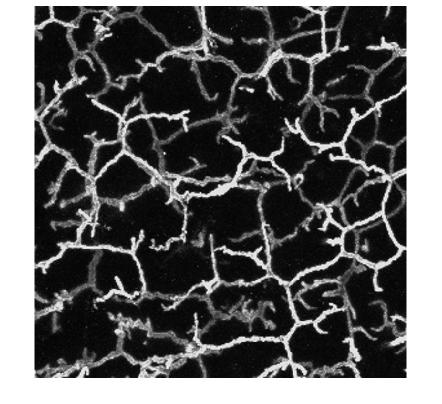

% declare data path
imPath = "data/blood_vessels.tif";

% 1. read in data
rawIm = imread(imPath);

% 2. convert data to grayscale image --> perhaps there is a built-in function
% to do this?
grayIm = mat2gray(rawIm);

% display image
imshow(grayIm);

## **ACTIVITY II: PRE-PROCESS AND SEGMENT BLOOD VESSELS FROM IMAGE**

### Complete the user-defined function obtainBinaryMask(): (15min)

- The expected input and output parameters are described within the function file. Use `graythresh()` and `imbinarize()` as described in the [documentation for `graythresh()`](https://www.mathworks.com/help/images/ref/graythresh.html). 

### Segment `grayIm` without any pre-processing steps: (cont.)

- Obtain a binary mask from `grayIm` by using `obtainBinaryMask()`.

- Display the obtained mask overlaid on `grayIm` by using `overlayMaskOnImage()`.

% 1. obtain binary mask
maskTemp = obtainBinaryMask(grayIm);

% 2. display obtained mask
overlaidMaskOnImage = overlayMaskOnImage(grayIm, maskTemp);
imshow(overlaidMaskOnImage);
title("Mask Results Without Pre-processing");

### Pre-procesing step 1: Denoising (5min)

- Smooth `grayIm` using `imgaussfilt()` and `sigma`. Use the [documentation of `imgaussfilt()`](https://www.mathworks.com/help/images/ref/imgaussfilt.html) for guidance.

- Obtain a binary mask from `blurIm` by using `obtainBinaryMask()`.

- Display the obtained mask overlaid on `grayIm` by using `overlayMaskOnImage()`.

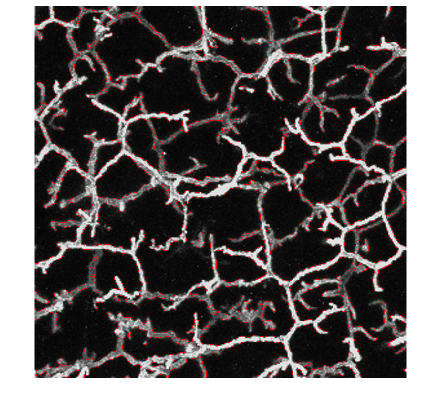

% 1. denoise image with gaussian blurring
sigma = 2.5; 
blurIm = imgaussfilt(grayIm, sigma);

% 2. obtain binary mask
blurMask = obtainBinaryMask(blurIm);

% 3. display obtained mask
overlaidBlurMaskOnImage = overlayMaskOnImage(grayIm, blurMask);
imshow(overlaidBlurMaskOnImage);

title("Mask Results After Denoising");

### Pre-processing step 2: Enhancing contrast (5min)

- Enhance the contrast of `blurIm` using `adapthisteq()`. Use the [documentation of `adapthisteq()`](https://www.mathworks.com/help/images/ref/adapthisteq.html#d126e9617) for guidance.

- Obtain a binary mask from `blurHistIm` by using `obtainBinaryMask()`.

- Display the obtained mask overlaid on `grayIm` by using `overlayMaskOnImage()`.

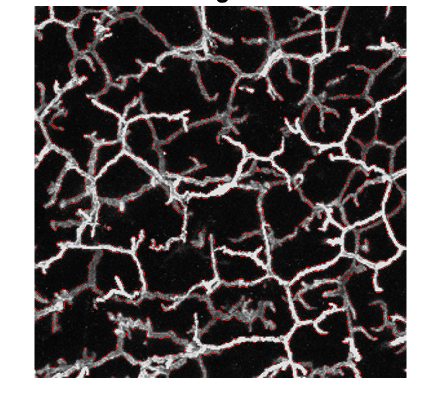

% 1. enhance contrast of image
blurHistIm = adapthisteq(blurIm);

% 2. obtain binary mask
blurHistMask = obtainBinaryMask(blurHistIm);

% 3. display obtained mask
overlaidBlurHistMaskOnImage = overlayMaskOnImage(grayIm, blurHistMask);
imshow(overlaidBlurHistMaskOnImage);
title("Mask Results After Denoising and Contrast Enhancement");

### Display segmentation results before and after pre-processing steps: (5min)

- Plot `overlaidMaskOnImage` and `overlaidBlurHistMaskOnImage` next to each other using `imshowpair()`. Use the [documentation of `imshowpair()`](https://www.mathworks.com/help/images/ref/imshowpair.html) for guidance on which "method" parameter to choose.

- Add a title the comparison plot.

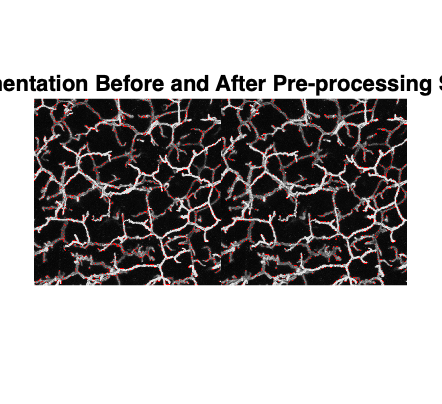

% 1. plot two images next to each other
% FILL IN CODE HERE
imshowpair(overlaidMaskOnImage, overlaidBlurHistMaskOnImage, "montage");

% 2. title this comparison plot appropiately
% FILL IN CODE HERE
title("Segmentation Before and After Pre-processing Steps");

### Remove small artifacts from final segmentation: (10min)

- Remove small artifacts from `blurHistMask` that have an area less than `threshArea` using `removeSmallArtifacts()`. The expected input and output parameters are described within the function file. 

- Display the mask before and after small artifact filtering next to each other using `imshowpair()`.

- Add a title the comparison plot.

% 1. remove small artifact from mask
threshArea = 250;
cleanedMask = removeSmallArtifacts(blurHistMask, threshArea);

% 2. display the mask before and after the small artifact filtering
% FILL IN CODE HERE
imshowpair(blurHistMask, cleanedMask, "montage");

% 3. title this comparison plot appropiately
% FILL IN CODE HERE
title("Segmentation Mask Before and After Removing Small Artifacts");

## **ACTIVITY III: PERFORM STRUCTURAL ANALYSIS ON BLOOD VESSEL SEGMENTATION MASK**

### Calculate blood vessel radii:

- Find the mid-line of every blood vessel using [`bwskel()`](https://www.mathworks.com/help/images/ref/bwskel.html) and the blood vessel segmentation mask.

- Obtain a blood vessel radii map. The variable `distanceMap` has been created for you. It is a matrix such that the value of every pixel within the blood vessel mask is the distance to the closest blood vessel perimeter. Determine what matrix operation can be done between the distanceMap and skeletonMask to obtain a matrix with only blood vessel radii values.

% define final mask and obtain distance map
mask = cleanedMask;

% 1. skeletonize blood vessel mask
skeletonMask = bwskel(mask);

% 2. obtain blood vessel radius for every pixel in skeleton mask
distanceMap = bwdist(~mask);    
radiiMap = distanceMap .* skeletonMask;  

## **ACTIVITY IV: VISUALIZE RESULTS USING PLOTTING FUNCTIONS**

### Plot a histogram of blood vessel radii: (10min)

- Get rid of all zero values in `radiiMap`. Use this MATLAB Answers thread on [logical indexing](https://www.mathworks.com/matlabcentral/answers/422002-how-does-logical-indexing-work) for guidance.

- Plot a [histogram](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html) displaying blood vessel radii distribution. Adjust `numBins` as needed. Add a title, and x and y axis labels.

% 1. get rid of all zero values in radiusMap
nonZeroRadii = radiiMap(radiiMap > 0);

% 2. plot blood vessel radii histogram 
numBins = 30;
% FILL IN CODE HERE
h = histogram(nonZeroRadii, numBins);
title('Histogram of Blood Vessel Radii Values');
xlabel('Radii Values (Pixels)');
ylabel('Frequency');

% Extra: Calculate midpoints of each bin (average value per bin)
binEdges = h.BinEdges;
binMidpoints = (binEdges(1:end-1) + binEdges(2:end)) / 2;
xticks(binMidpoints(1:2:end));
xtickformat("%.1f")

### Plot a heat map of the distance map: (10min)

- Plot the `distanceMap` as a heat map using the function [`imagesc()`](https://www.mathworks.com/help/matlab/ref/imagesc.html). Change the colour map to "hot", add a colour scale bar, and title.

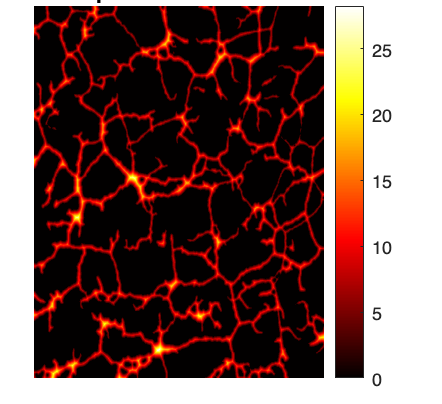

% 1. plot the distance map as a heat map
axis image;     % maintains aspect ratio of image
% FILL IN CODE HERE
imagesc(distanceMap);
colormap('hot'); 
colorbar; 
axis off;
title('Heat Map of Blood Vessel Width');

### Display both plots beside each other: (10min)

- Use [`subplot()`](https://www.mathworks.com/help/matlab/ref/subplot.html) to display the plots from steps 2 and 3 next to each other in a row.

- Optional: Explore [MATLAB plotting customizations](https://www.mathworks.com/help/matlab/formatting-and-annotation.html) to change colour schemes, axes appearance, etc.

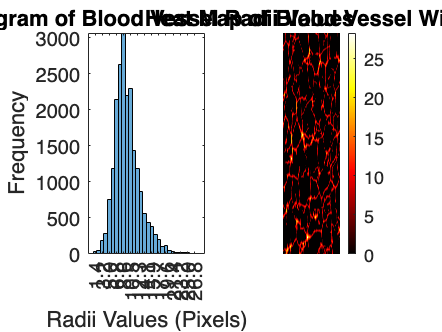

% 1. display both plots next to each other in one figure
% FILL IN CODE HERE
figure;
subplot(1,2,1);
h = histogram(nonZeroRadii, numBins);
title('Histogram of Blood Vessel Radii Values');
xlabel('Radii Values (Pixels)');
ylabel('Frequency');
binEdges = h.BinEdges;
binMidpoints = (binEdges(1:end-1) + binEdges(2:end)) / 2;
xticks(binMidpoints(1:2:end));
xtickformat("%.1f")

subplot(1,2,2);
imagesc(distanceMap);
colormap('hot'); 
colorbar; 
axis off;
title('Heat Map of Blood Vessel Width');